% A4
% Transger Function for G0
G0 = zpk([-1], [-2 -3], 1)

G0 =
 
     (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties



% Unity feedback system
H0 = feedback(1, G0);

% Ess for Step Input
steadyStateValue_G0 = dcgain(H0);
errorStepInput_G0 = 1 - steadyStateValue_G0;

% Error Coefficient and Theoretical Steady State Error
poles_G0 = pole(G0);
KP_G0 = 1 / prod(poles_G0);
theoreticalError_G0 = 1 / (1 + KP_G0);

% Results
disp('Type 0 System (G0):');

Type 0 System (G0):


disp(['Steady State Value: ', num2str(steadyStateValue_G0)]);

Steady State Value: 0.85714


disp(['Error for Step Input: ', num2str(errorStepInput_G0)]);

Error for Step Input: 0.14286


disp(['Error Coefficient: ', num2str(KP_G0)]);

Error Coefficient: 0.16667


disp(['Theoretical Steady State Error: ', num2str(theoreticalError_G0)]);

Theoretical Steady State Error: 0.85714


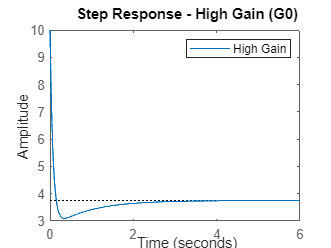


% Change Gain
K_G0_highGain = 10;
H0_highGain = feedback(K_G0_highGain, G0);

% Effect on Accuracy
figure;
step(H0_highGain);
title('Step Response - High Gain (G0)');
legend('High Gain');

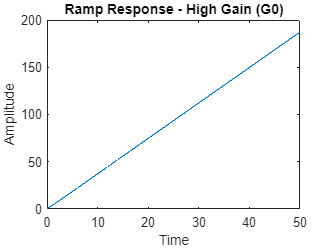


% Response to a Ramp Input
time = 0:0.01:50;  
alpha = 1;
ramp = alpha * time; % Ramp input

% Simulate
rampResponse_G0_highGain = lsim(H0_highGain, ramp, time);

% Response
figure;
plot(time, rampResponse_G0_highGain);
title('Ramp Response - High Gain (G0)');
xlabel('Time');
ylabel('Amplitude');

% Transfer Function for G1
G1 = zpk([-1], [0 -2 -3], 1)

G1 =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties



% Reset Gain and Remove Integrator
H1 = feedback(1, G1);

% Step response and error analysis
sisotool(H1);
step(H1);
finalValue_G1 = step(H1);
error_G1 = 1 - finalValue_G1;

% Ess for Gain
fprintf('G1 - Step Error: %f\n', error_G1);

G1 - Step Error: 0.000000
G1 - Step Error: 0.000689
G1 - Step Error: 0.002621
G1 - Step Error: 0.005614
G1 - Step Error: 0.009505
G1 - Step Error: 0.014154
G1 - Step Error: 0.019434
G1 - Step Error: 0.025239
G1 - Step Error: 0.031471
G1 - Step Error: 0.038049
G1 - Step Error: 0.044900
G1 - Step Error: 0.051962
G1 - Step Error: 0.059180
G1 - Step Error: 0.066509
G1 - Step Error: 0.073908
G1 - Step Error: 0.081344
G1 - Step Error: 0.088789
G1 - Step Error: 0.096217
G1 - Step Error: 0.103608
G1 - Step Error: 0.110947
G1 - Step Error: 0.118219
G1 - Step Error: 0.125412
G1 - Step Error: 0.132520
G1 - Step Error: 0.139533
G1 - Step Error: 0.146448
G1 - Step Error: 0.153260
G1 - Step Error: 0.159967
G1 - Step Error: 0.166569
G1 - Step Error: 0.173063
G1 - Step Error: 0.179451
G1 - Step Error: 0.185733
G1 - Step Error: 0.191910
G1 - Step Error: 0.197985
G1 - Step Error: 0.203960
G1 - Step Error: 0.209836
G1 - Step Error: 0.215617
G1 - Step Error: 0.221306
G1 - Step Error: 0.226904
G1 - Step Er

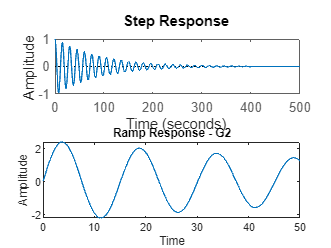


% Ramp Response
time = 0:0.01:50;  
alpha = 1;
ramp = alpha * time; % Ramp Input

% Simulate the Response to a Ramp Input for G1
rampResponse_G1 = lsim(H1, ramp, time);

% Plot the Responses
figure;
subplot(2, 1, 1);
plot(time, rampResponse_G1);
title('Ramp Response - G1');
xlabel('Time');
ylabel('Amplitude');

% Transfer Function for G2
G2 = zpk([-1], [0 0 -2 -3], 1)

G2 =
 
       (s+1)
  ---------------
  s^2 (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties



% Increase time limit for analysis
% sisotool('TimeRange', [0 100]);

% Unity feedback system
H2 = feedback(1, G2);

% Step response and error calculations
sisotool(H2);
step(H2);
finalValue_G2 = step(H2);
error_G2 = 1 - finalValue_G2;

% Steady-state error for step and ramp inputs
fprintf('G2 - Step error: %f\n', error_G2);

G2 - Step error: 0.000000
G2 - Step error: 0.036860
G2 - Step error: 0.180359
G2 - Step error: 0.411236
G2 - Step error: 0.698654
G2 - Step error: 1.011405
G2 - Step error: 1.318041
G2 - Step error: 1.588726
G2 - Step error: 1.797743
G2 - Step error: 1.925825
G2 - Step error: 1.961896
G2 - Step error: 1.903997
G2 - Step error: 1.759324
G2 - Step error: 1.543376
G2 - Step error: 1.278308
G2 - Step error: 0.990674
G2 - Step error: 0.708770
G2 - Step error: 0.459863
G2 - Step error: 0.267560
G2 - Step error: 0.149576
G2 - Step error: 0.116116
G2 - Step error: 0.169011
G2 - Step error: 0.301677
G2 - Step error: 0.499899
G2 - Step error: 0.743338
G2 - Step error: 1.007605
G2 - Step error: 1.266700
G2 - Step error: 1.495562
G2 - Step error: 1.672483
G2 - Step error: 1.781163
G2 - Step error: 1.812197
G2 - Step error: 1.763876
G2 - Step error: 1.642221
G2 - Step error: 1.460270
G2 - Step error: 1.236697
G2 - Step error: 0.993899
G2 - Step error: 0.755767
G2 - Step error: 0.545336
G2 - Step er


% Ramp response
time = 0:0.1:50; % Adjust time vector as needed
alpha = 1;
ramp = time; % Ramp input

% Simulate the response to a ramp input for G2
rampResponse_G2 = lsim(H2, ramp, time);

% Plot the responses
subplot(2, 1, 2);
plot(time, rampResponse_G2);
title('Ramp Response - G2');
xlabel('Time');
ylabel('Amplitude');

% Confirm expected behavior
fprintf('Confirmed expected steady-state errors for G2.\n');

Confirmed expected steady-state errors for G2.
